# **Controllo di un Falcon 9**

Si consideri un modello semplificato del Falcon 9, razzo della nota compagnia aerospaziale SpaceX.

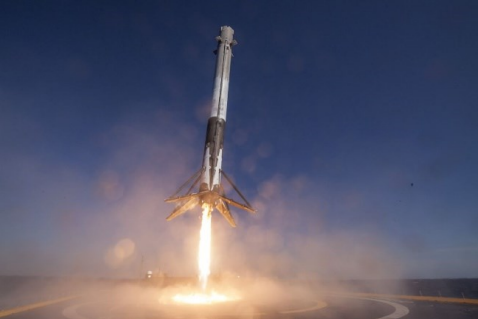

## Modellazione del sistema

Come altri sistemi di propulsione di SpaceX, il Falcon 9 è stato progettato per consentire il controllo dell'atterraggio e, quindi, il suo riutilizzo. Si semplifichi il modello ad un disco circolare di 20 metri di diametro e composto da due propulsori.

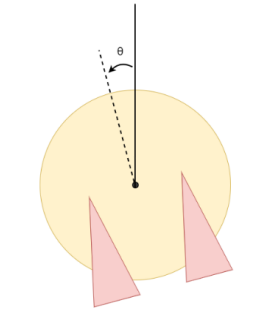

### Equazioni di stato

Considerando come variabili di stato:

- $x_1 \left(t\right)$ la posizione del centro di gravità sull'asse x

- $x_2 \left(t\right)$ la posizione del centro di gravità sull'asse y

- $x_3 \left(t\right)$ l'inclinazione rispetto al centro di gravità

- $x_4 \left(t\right)$ la componente di velocità del centro di gravità sull'asse x

- $x_5 \left(t\right)$ la componente di velocità del centro di gravità sull'asse y

- $x_6 \left(t\right)$ la velocità angolare rispetto al centro di gravità

come variabili di ingresso:

- $u_1 \left(t\right)$ la spinta del propulsore sinistro

- $u_2 \left(t\right)$ la spinta del propulsore destro

e come variabili di uscita le variabili di stato, la dinamica del sistema può essere espressa dalle seguenti equazioni di stato:


$$\begin{cases}
\dot{x}_1(t) = x_4(t) \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \  \\
\dot{x}_2(t) = x_5(t) \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \  \\
\dot{x}_3(t) = x_6(t) \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \\
\dot{x}_4(t) = -\frac{\sin x_3(t)\left(u_1(t)+u_2(t)\right)}{M} \ \ \\
\dot{x}_5(t) = \frac{\cos x_3(t)\left(u_1(t)+u_2(t)\right)}{M} -g \\
\dot{x}_6(t) =\frac{L_2 \left(u_2(t) - u_1(t)\right)}{J} \ \ \ \ \ \ \ \ 
\end{cases}$$


### Parametri del sistema

Si considerino, come parametri del sistema, le seguenti quantità:

- $M=1\;\textrm{kg}$ massa del razzo

- $g=9\ldotp 81\;\frac{\mathrm{m}}{\mathrm{s}}$ costante gravitazionale

- $L_1 =10\;\mathrm{m}$ centro di gravità dalle estremità superiore e inferiore

- $L_2 =5\;\mathrm{m}$ centro di gravità dai propulsori sinistro e destro

- $J=\frac{1}{2}{\textrm{ML}}_1 =5\;\textrm{kg}\cdot {\mathrm{m}}^2$ momento di inerzia rispetto all'asse pitch

## Implementazione del sistema

% Operazioni preliminari
close all;
clear all;
clc;

### Funzione di stato

Poiché il sistema descritto è non lineare, occorre dichiarare separatamente la funzione di stato ([`f9StateFunction.m`](matlab:open('./f9StateFunction.m'))`).`

### Jacobiano analitico della funzione di stato

La funzione di stato può essere differenziata rispetto alle variabili di stato ed alle variabili di ingresso.

Differenziando la funzione di stato rispetto alle variabili di stato si ottiene la matrice:


$$A=\frac{\partial f\left(x,u\right)}{\partial x}=\left\lbrack \begin{array}{cccccc}
\frac{\partial f_1 }{\partial x_1 } & \frac{\partial f_1 }{\partial x_2 } & \frac{\partial f_1 }{\partial x_3 } & \frac{\partial f_1 }{\partial x_4 } & \frac{\partial f_1 }{\partial x_5 } & \frac{\partial f_1 }{\partial x_6 }\\
\frac{\partial f_2 }{\partial x_1 } & \frac{\partial f_2 }{\partial x_2 } & \frac{\partial f_2 }{\partial x_3 } & \frac{\partial f_2 }{\partial x_4 } & \frac{\partial f_2 }{\partial x_5 } & \frac{\partial f_2 }{\partial x_6 }\\
\frac{\partial f_3 }{\partial x_1 } & \frac{\partial f_3 }{\partial x_2 } & \frac{\partial f_3 }{\partial x_3 } & \frac{\partial f_3 }{\partial x_4 } & \frac{\partial f_3 }{\partial x_5 } & \frac{\partial f_3 }{\partial x_6 }\\
\frac{\partial f_4 }{\partial x_1 } & \frac{\partial f_4 }{\partial x_2 } & \frac{\partial f_4 }{\partial x_3 } & \frac{\partial f_4 }{\partial x_4 } & \frac{\partial f_4 }{\partial x_5 } & \frac{\partial f_4 }{\partial x_6 }\\
\frac{\partial f_5 }{\partial x_1 } & \frac{\partial f_5 }{\partial x_2 } & \frac{\partial f_5 }{\partial x_3 } & \frac{\partial f_5 }{\partial x_4 } & \frac{\partial f_5 }{\partial x_5 } & \frac{\partial f_5 }{\partial x_6 }\\
\frac{\partial f_6 }{\partial x_1 } & \frac{\partial f_6 }{\partial x_2 } & \frac{\partial f_6 }{\partial x_3 } & \frac{\partial f_6 }{\partial x_4 } & \frac{\partial f_6 }{\partial x_5 } & \frac{\partial f_6 }{\partial x_6 }
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & 0 & 0 & 1\\
0 & 0 & -\frac{\cos \;x_3 \left(t\right)\left(u_1 \left(t\right)+u_2 \left(t\right)\right)}{M} & 0 & 0 & 0\\
0 & 0 & -\frac{\sin \;x_3 \left(t\right)\left(u_1 \left(t\right)+u_2 \left(t\right)\right)}{M} & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack$$


Differenziando la funzione di stato rispetto alle variabili di ingresso si ottiene la matrice:


$$B=\frac{\partial f\left(x,u\right)}{\partial u}=\left\lbrack \begin{array}{cc}
\frac{\partial f_1 }{\partial u_1 } & \frac{\partial f_1 }{\partial u_2 }\\
\frac{\partial f_2 }{\partial u_1 } & \frac{\partial f_2 }{\partial u_2 }\\
\frac{\partial f_3 }{\partial u_1 } & \frac{\partial f_3 }{\partial u_2 }\\
\frac{\partial f_4 }{\partial u_1 } & \frac{\partial f_4 }{\partial u_2 }\\
\frac{\partial f_5 }{\partial u_1 } & \frac{\partial f_5 }{\partial u_2 }\\
\frac{\partial f_6 }{\partial u_1 } & \frac{\partial f_6 }{\partial u_2 }
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0\\
0 & 0\\
-\frac{\sin \;x_3 \left(t\right)}{M} & -\frac{\sin \;x_3 \left(t\right)}{M}\\
\frac{\cos \;x_3 \left(t\right)}{M} & \frac{\cos \;x_3 \left(t\right)}{M}\\
-\frac{L_2 }{J} & \frac{L_2 }{J}
\end{array}\right\rbrack$$


I risultati ottenuti permettono di definire la funzione per lo Jacobiano analitico della funzione di stato ([`f9StateJacobian.m`](matlab:open('./f9StateJacobian.m'))).

% Jacobiano analitico della funzione di stato
nlobj.Jacobian.StateFcn = 'f9StateJacobian';

## Implementazione del controllore

Una volta implementato il sistema non lineare attraverso la sua funzione di stato, è necessario definire il controllore MPC.

% Numero di stati
nx = 6;

% Numero di uscite
ny = 6;

% Numero di ingressi
nu = 2;

Il fatto che il numero di uscite sia uguale al numero di stati implica che tutti gli stati del sistema siano misurabili.

### Definizione del controllore

% Controllore MPC
nlobj = nlmpc(nx,ny,nu);

Poiché il numero di uscite è maggiore del numero di ingressi, di default MATLAB assegna un peso nullo sulle uscite eccedenti il numero di ingressi. In questo caso, poiché gli ingressi sono 2 e le uscite sono 6, alla terza, alla quarta, alla quinta ed alla sesta uscita viene assegnato un peso nullo.

### Funzioni del sistema

Occorre specificare la funzione di stato e la funzione di uscita del sistema non lineare.

% Funzione di stato
nlobj.Model.StateFcn = 'f9StateFunction';

### Verifica della correttezza dei calcoli

Per verificare se lo Jacobiano analitico per la funzione di stato sia stato calcolati correttamente, è possibile validare il comportamento della funzione a fronte di un set casuale di stati e ingressi.

% Verifica
validateFcns(nlobj,rand(6,1),rand(2,1));

## Richiesta 1

Si vuole che il tempo di assestamento sia di 2 secondi. I sensori montati sul razzo operano a 5 Hz. Scegliere valori appropriati del periodo di campionamento e dell'orizzonte di predizione. Si consideri un orizzonte di controllo pari a 5.

### Scelta dei parametri del controllore

Usualmente si desidera un periodo di campionamento che sia compreso tra il 10% ed il 25% del tempo di assestamento. Occorre tuttavia tener conto del comportamento dei sensori montati sul razzo, che operando ad una frequenza di 5 Hz limitano il periodo di campionamento a 0.2 secondi. Si osserva che 0.2 secondi corrisponde proprio al 10% del tempo di assestamento, pertanto può essere considerato come un valore corretto da assegnare al periodo di campionamento.

Noti il tempo di assestamento desiderato ed il periodo di campionamento, l'orizzonte di predizione è dato dalla relazione:


$$t_s \approx T_s \cdot H_p \;\;\;\Rightarrow \;\;H_p =\frac{t_s }{T_s }=\frac{2}{0\ldotp 2}=10$$


% Periodo di campionamento [s]
Ts = 0.1;

% Orizzonte di predizione
Hp = 8;

% Orizzonte di controllo
Hc = 5;

Scelti i parametri del controllore, si procede con l'assegnazione

% Periodo di campionamento
nlobj.Ts = Ts;

% Orizzonte di predizione
nlobj.PredictionHorizon = Hp;

% Orizzonte di controllo
nlobj.ControlHorizon = Hc;

## Richiesta 2

Si assumano le seguenti condizioni iniziali per il sistema:

% Condizioni iniziali
x0 = [-30; 100; 0; 0; 0; 0;];
u0 = [0; 0];

ed il seguente riferimento:

% Riferimento
ref = [0, 10, 0, 0, 0, 0];

Si vuole che la massima spinta fornita dai propulsori sia di 8 N (le spinte dei propulsori sono esclusivamente positive). Se il razzo risente di un overshoot importante sull'altezza durante l'atterraggio, esplode. Vincolare il sistema appropriatamente, eseguire una simulazione di 20 secondi, plottare l'evoluzione degli stati e degli ingressi e commentare i risultati ottenuti.

### Definizione di vincoli sugli ingressi

Si vincola il sistema secondo le limitazioni imposte.

% Vincolo sul valore massimo degli ingressi
nlobj.ManipulatedVariables(1).Max = 8;
nlobj.ManipulatedVariables(2).Max = 8;

% Vincolo sul valore minimo degli ingressi
nlobj.ManipulatedVariables(1).Min = 0;
nlobj.ManipulatedVariables(2).Min = 0;

### Simulazione del controllo

Vincolato il sistema, si esegue la simulazione richiesta.

% Durata della simulazione
Tf = 20;

% Vettore dei tempi
t = 0:Ts:Tf;

% Step della simulazione
N = length(t);

% Inizializzazione
xk = x0;
mv = u0;

% Inizializzazione degli stati
x_history = zeros(6,N);

% Inizializzazione delle uscite
y_history = zeros(6,N);

% Inizializzazione degli ingressi
u_history = zeros(2,N);

% Ciclo di controllo
for i=1:N

    [mv,~,info] = nlmpcmove(nlobj,xk,mv,ref);

    % Controllo
    xk = info.Xopt(2,:);
    y = info.Yopt(1,:);

    % Aggiornamento
    x_history(:,i) = xk;
    y_history(:,i) = y;
    u_history(:,i) = mv;
end

### Analisi dei risultati

% Evoluzione degli ingressi
figure
for i=1:2
    subplot(2,1,i);
    stairs(t,u_history(i,:));
    ylim([-1 9]), ylabel("u" + i), grid minor;
end
sgtitle('Inputs', 'FontWeight', 'bold');

% Evoluzione degli stati
figure
for i=1:6
    subplot(3,2,i);
    plot(t,x_history(i,:));
    grid minor, hold on,
    yline(ref(i)), ylabel("x" + i);
end
sgtitle('States', 'FontWeight', 'bold');

I risultati della simulazione condotta evidenziano in primo luogo come i vincoli sugli ingressi siano soddisfatti:

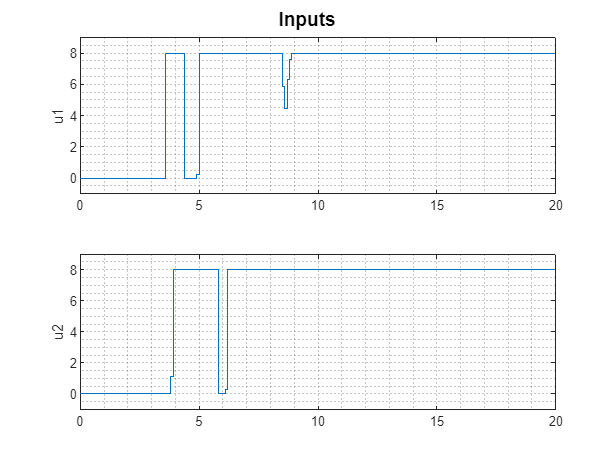

ed in secondo luogo come l'andamento degli stati, tra i quali le posizioni del centro di gravità sull'asse x e sull'asse y, sia soggetti a forti oscillazioni che comportano l'esplosione del razzo e che quindi devono essere opportunamente gestite.

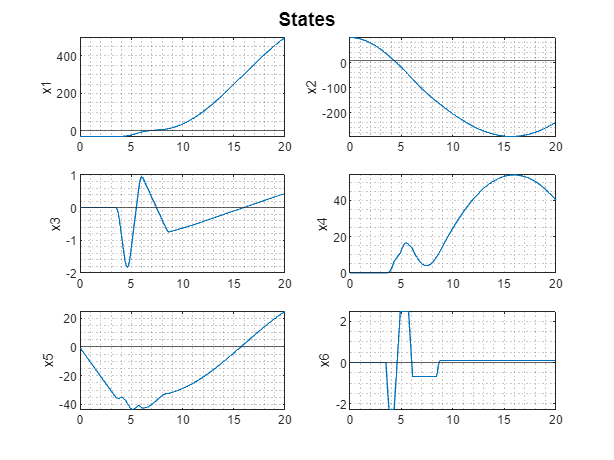

### Definizione di un vincolo sullo stato

Dall'evoluzione dell'altezza durante l'atterraggio, cioè del secondo stato del sistema, si osserva una discesa ben oltre al di sotto del valore di riferimento. Si può allora vincolare lo stato in modo che la posizione raggiunta sia quella minima.

% Vincolo sul valore minimo del secondo stato
nlobj.States(2).Min = 10;

### Simulazione del controllo

Vincolato ulteriormente il sistema, si ripete la simulazione.

% Durata della simulazione
Tf = 20;

% Vettore dei tempi
t = 0:Ts:Tf;

% Step della simulazione
N = length(t);

% Inizializzazione
xk = x0;
mv = u0;

% Inizializzazione degli stati
x_history = zeros(6,N);

% Inizializzazione delle uscite
y_history = zeros(6,N);

% Inizializzazione degli ingressi
u_history = zeros(2,N);

% Ciclo di controllo
for i=1:N

    [mv,~,info] = nlmpcmove(nlobj,xk,mv,ref);

    % Controllo
    xk = info.Xopt(2,:);
    y = info.Yopt(1,:);

    % Aggiornamento
    x_history(:,i) = xk;
    y_history(:,i) = y;
    u_history(:,i) = mv;
end

### Analisi dei risultati

% Evoluzione degli ingressi
figure
for i=1:2
    subplot(2,1,i);
    stairs(t,u_history(i,:));
    ylim([-1 9]), ylabel("u" + i), grid minor;
end
sgtitle('Inputs', 'FontWeight', 'bold');

% Evoluzione degli stati
figure
for i=1:6
    subplot(3,2,i);
    plot(t,x_history(i,:));
    grid minor, hold on,
    yline(ref(i)), ylabel("x" + i);
end
sgtitle('States', 'FontWeight', 'bold');

I risultati della simulazione condotta evidenziano un miglioramento nell'andamento della seconda variabile di stato e la comparsa di due forti oscillazioni nell'andamento della prima variabile di stato che si traducono un traballio del razzo.

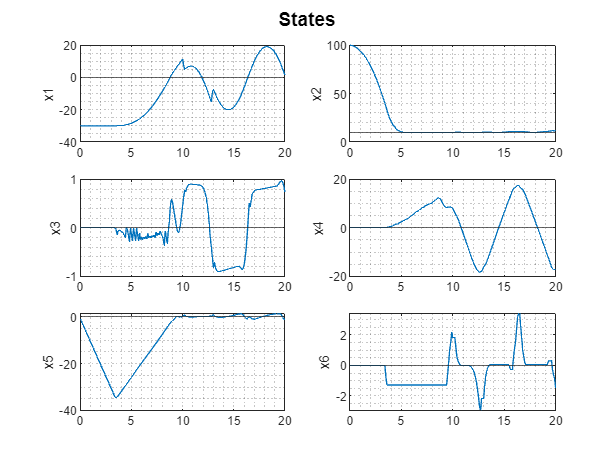

## Richiesta 3

Come si è visto dai risultati della simulazione, il sistema è soggetto ad un forte overshoot. Su quali parametri si dovrebbe agire per ridurre l'overshoot? Una volta eseguite le modifiche, ripetere la simulazione e commentare i risultati ottenuti.

### Aggiornamento dell'orizzonte di predizione

Avendo già definito dei vincoli sugli ingressi e su uno stato, il parametro sul quale agire per ridurre l'overshoot è verosimilmente l'orizzonte di predizione. Si può pensare di incrementarlo di molto, essendo un sistema ad elevata criticità.

% Orizzonte di predizione
nlobj.PredictionHorizon = 50;

### Simulazione del controllo

Si ripete la simulazione per verificare se le modifiche migliorano il controllo del sistema.

% Durata della simulazione
Tf = 20;

% Vettore dei tempi
t = 0:Ts:Tf;

% Step della simulazione
N = length(t);

% Inizializzazione
xk = x0;
mv = u0;

% Inizializzazione degli stati
x_history = zeros(6,N);

% Inizializzazione delle uscite
y_history = zeros(6,N);

% Inizializzazione degli ingressi
u_history = zeros(2,N);

% Ciclo di controllo
for i=1:N

    [mv,~,info] = nlmpcmove(nlobj,xk,mv,ref);

    % Controllo
    xk = info.Xopt(2,:);
    y = info.Yopt(1,:);

    % Aggiornamento
    x_history(:,i) = xk;
    y_history(:,i) = y;
    u_history(:,i) = mv;
end

### Analisi dei risultati

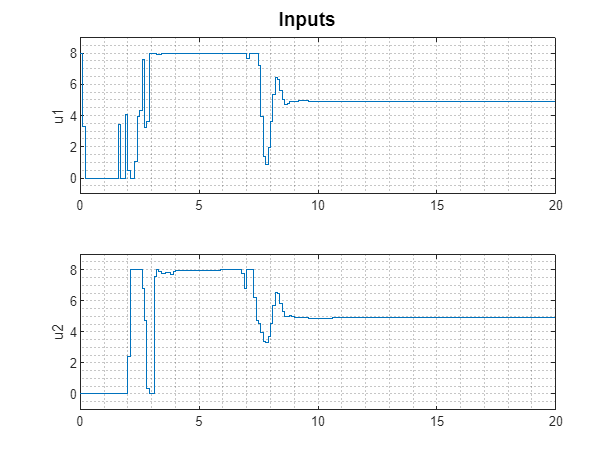

% Evoluzione degli ingressi
figure
for i=1:2
    subplot(2,1,i);
    stairs(t,u_history(i,:));
    ylim([-1 9]), ylabel("u" + i), grid minor;
end
sgtitle('Inputs', 'FontWeight', 'bold');

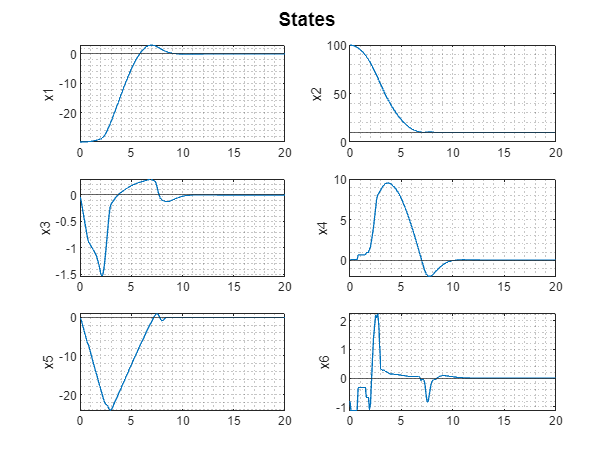


% Evoluzione degli stati
figure
for i=1:6
    subplot(3,2,i);
    plot(t,x_history(i,:));
    grid minor, hold on,
    yline(ref(i)), ylabel("x" + i);
end
sgtitle('States', 'FontWeight', 'bold');

I risultati della simulazione condotta evidenziano un atterraggio molto più preciso, sia in termini di posizione che di velocità.

### Simulazione ottimizzata del controllo

Un rapido sguardo alla base dei tempi evidenzia la stabilizzazione del razzo in circa 12 secondi. Ciò significa che per la restante durata della simulazione si stanno sprecando risorse, pertanto si può pensare di interrompere l'esecuzione della simulazione in corrispondenza di un valore soddisfacente dell'errore commesso (al di sotto di una certa soglia).

% Durata della simulazione
Tf = 20;

% Vettore dei tempi
t = 0:Ts:Tf;

% Step della simulazione
N = length(t);

% Inizializzazione
xk = x0;
mv = u0;

% Inizializzazione degli stati
x_history = zeros(6,N);

% Inizializzazione delle uscite
y_history = zeros(6,N);

% Inizializzazione degli ingressi
u_history = zeros(2,N);

% Ciclo di controllo
i = 1;
while true

    [mv,~,info] = nlmpcmove(nlobj,xk,mv,ref);

    % Controllo
    xk = info.Xopt(2,:);
    y = info.Yopt(1,:);

    % Aggiornamento
    x_history(:,i) = xk;
    y_history(:,i) = y;
    u_history(:,i) = mv;

    % Criterio di arresto
    if (xk-ref)'*(xk-ref) < 0.1
        break
    end

    i = i + 1;
end

### Analisi dei risultati

I risultati della simulazione possono essere meglio interpretati considerando la seguente animazione:

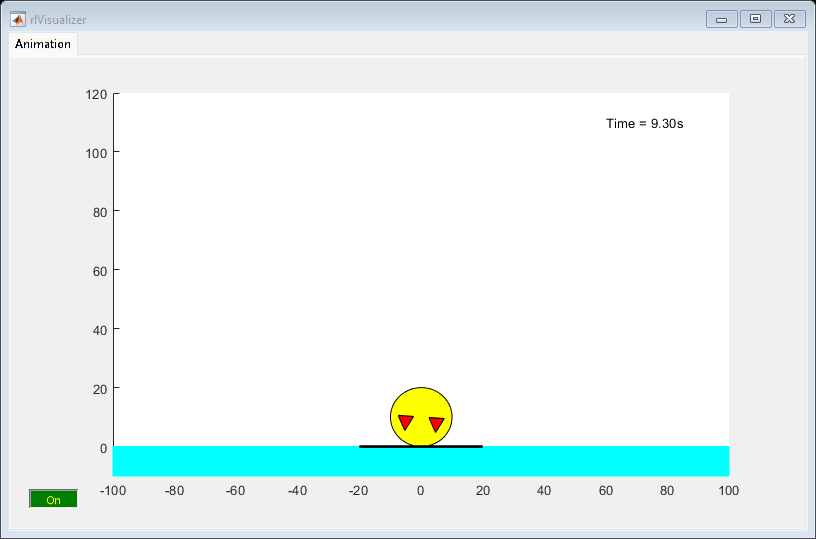

% Evoluzione degli ingressi
plotobj = RocketAnimation(6,2);
for j=1:(i-1)
    updatePlot(plotobj,(j-1)*Ts,x_history(:,j),u_history(:,j));
    pause(0.1);
end

## Richiesta 5

Analizzare il tempo computazionale richiesto per ciascun aggiornamento. Usando il periodo di campionamento e l'orizzonte di predizione scelti in fase di progetto, è possibile controllare il sistema in real time?

### Valutazione del tempo computazionale

% Durata della simulazione
Tf = 20;

% Vettore dei tempi
t = 0:Ts:Tf;

% Step della simulazione
N = length(t);

% Inizializzazione
xk = x0;
mv = u0;

% Inizializzazione degli stati
x_history = zeros(6,N);

% Inizializzazione delle uscite
y_history = zeros(6,N);

% Inizializzazione degli ingressi
u_history = zeros(2,N);

% Inizializzazione del tempo computazionale
t_history = zeros(1,N);

% Ciclo di controllo
i = 1;
while true

    tic;

    [mv,~,info] = nlmpcmove(nlobj,xk,mv,ref);

    % Controllo
    xk = info.Xopt(2,:);
    y = info.Yopt(1,:);

    % Aggiornamento
    t_history(:,i) = toc;
    x_history(:,i) = xk;
    y_history(:,i) = y;
    u_history(:,i) = mv;

    % Criterio di arresto
    if (xk-ref)'*(xk-ref) < 0.1
        break
    end

    i = i + 1;
end

% Vettore dei tempi aggiornato
t = 0:Ts:(i-1)*Ts;

### Analisi dei risultati

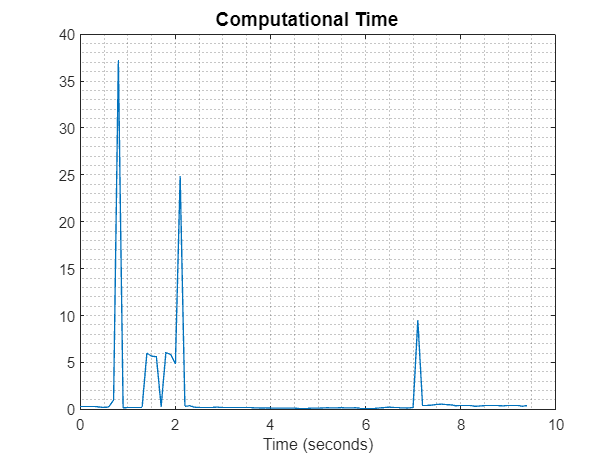

% Evoluzione del tempo computazionale
figure
plot(t,t_history(1,1:i));
grid minor, xlabel("Time (seconds)");
sgtitle('Computational Time', 'FontWeight', 'bold');

Poiché sono presenti diversi picchi in corrispondenza dei quali il tempo computazionale supera di gran lunga il periodo di campionamento, per via delle scelte effettuate in fase di progettazione non è possibile eseguire il controllo in real time.